# 提取刺激开始的时间

初始化程序

clc; clear; close all;

读取文件

folder_path = '../Data/M30_0420';
txtFiles = dir(fullfile(folder_path, '*.txt'));
trigger_file = fullfile(folder_path, txtFiles(1).name);  % change here with the position of your trigger file

将此行中的File文件的索引更改为对应的文件索引

trigger = importdata(trigger_file);

try
    matFiles = dir(fullfile(folder_path, 'video*.mat'));
    sti_info_file = fullfile(folder_path, matFiles(1).name);
    sti_info = importdata(sti_info_file);
catch
end

t_selected_image = [];
t_selected_vis = [];

设置参数

fre = 4;                            % 显微镜拍摄频率
sample=0.005;                       % Trigger采样频率
sample_frame = 1/sample;

IPD = 6;                            % replace with your own stimulus presentation time
ISI = 4;                            % replace with your own ISI

isi = IPD+ISI; 

显微镜信号为1的索引

indices = find(trigger(:,2)==1)';

将所有连续的索引取为均值

% 初始化新的索引和计数器
new_indices = [];
count = 1;

for i = 1:numel(indices)-1
    if indices(i+1) - indices(i) == 1
        % 如果当前索引和下一个索引连续，则继续累加到计数器中
        count = count + 1;
    else
        % 如果不连续，则计算之前连续索引的平均值并添加到新索引中
        avg_index = mean(indices(i-count+1:i));
        new_indices = [new_indices, avg_index];
        count = 1; % 重置计数器
    end
end

% 处理最后一段连续的索引
if count > 1
    avg_index = mean(indices(end-count+1:end));
    new_indices = [new_indices, avg_index];
else
    new_indices = [new_indices, indices(end)]; % 添加最后一个索引
end

将刺激信号平滑

% plot(trigger(:,3));                     % 光敏电阻（刺激）信号           
noisy_square_wave = trigger(:,3);
window_size = 10; % 滑动窗口大小
for i = 1:length(noisy_square_wave)-window_size
    window = noisy_square_wave(i:i+window_size-1);
    if sum(window) <= 1 || sum(window) >= window_size - 1 % 如果窗口内只有0或者只有1，则修复突变点
        noisy_square_wave(i+floor(window_size/2)) = mode(window);
    end
end

%noisy_square_wave(1:5000) = 0;
stimulus = noisy_square_wave;

利用拍摄帧对刺激进行索引

square_wave = stimulus(round(new_indices));
% plot(square_wave);

将每个刺激出现的时间记录下来

% 初始化变量
start_times = [];
end_times = [];
current_state = square_wave(1);
start_time = 1;

% 遍历信号
for i = 2:length(square_wave)
    if square_wave(i) ~= current_state % 如果当前点与前一个点的状态不同
        if square_wave(i) == 1 % 如果当前点为1，则记录起始时间
            start_times = [start_times start_time];
        else % 如果当前点为0，则记录结束时间
            end_times = [end_times i];
        end
        current_state = square_wave(i); % 更新当前状态
        start_time = i; % 更新起始时间
    end
end

% 输出每个波的起始时间和结束时间
disp('Start times:');
disp(start_times);
disp('End times:');
disp(end_times);

  列 1 至 2,730

          30          77         123         169         215         262         308         354         400         446         492         538         584         630         672         718         764         810         856         902         948         993        1039        1085        1131        1177        1224        1313        1359        1404        1450        1496        1541        1588        1635        1681        1728        1774        1821        1868        1913        1960        2006        2053        2099        2146        2192        2239        2285        2332        2378        2424        2471        2517        2563        2610        2656        2703        2749        2796        2842        2889        2935        2982        3028        3074        3121        3168        3214        3261        3307        3354        3400        3446        3493        3539        3586        3632        3678        3725        3772        3819 

   1.0e+03 *

    0.0002
    0.0004
    0.0006
    0.0009
    0.0011
    0.0014
    0.0016
    0.0018
    0.0021
    0.0023
    0.0026
    0.0028
    0.0030
    0.0033
    0.0035
    0.0037
    0.0040
    0.0042
    0.0045
    0.0047
    0.0049
    0.0052
    0.0054
    0.0057
    0.0059
    0.0061
    0.0064
    0.0069
    0.0071
    0.0073
    0.0076
    0.0078
    0.0081
    0.0083
    0.0085
    0.0088
    0.0090
    0.0092
    0.0095
    0.0097
    0.0100
    0.0102
    0.0104
    0.0107
    0.0109
    0.0112
    0.0114
    0.0116
    0.0119
    0.0121
    0.0124
    0.0126
    0.0128
    0.0131
    0.0133
    0.0136
    0.0138
    0.0140
    0.0143
    0.0145
    0.0147
    0.0150
    0.0152
    0.0155
    0.0157
    0.0159
    0.0162
    0.0164
    0.0167
    0.0169
    0.0171
    0.0174
    0.0176
    0.0179
    0.0181
    0.0183
    0.0186
    0.0188
    0.0191
    0.0193
    0.0195
    0.0198
    0.0200
    0.0202
    0.0205
    0.0207
    0.0210
    0.0212
    0.0214
    0.0

ans = 16.6983

ans = 4008

  列 1 至 3,276

   46.5000   46.0000   46.5000   46.0000   46.5000   46.0000   46.0000   46.0000   46.0000   46.0000   46.0000   46.0000   46.0000   42.0000   46.0000   46.0000   46.0000   46.0000   46.0000   46.0000   45.5000   45.5000   46.0000   46.0000   46.5000   46.5000   89.0000   46.0000   45.5000   45.5000   46.0000   45.0000   47.0000   47.0000   46.5000   46.5000   46.5000   46.5000   47.0000   45.5000   46.5000   46.5000   46.5000   46.0000   47.0000   46.0000   47.0000   46.0000   47.0000   46.0000   46.5000   46.5000   46.0000   46.5000   46.5000   46.5000   46.5000   46.5000   46.5000   46.5000   46.5000   46.5000   46.5000   46.0000   46.5000   46.5000   47.0000   46.5000   46.5000   46.5000   46.5000   46.0000   46.5000   46.5000   46.5000   46.5000   46.0000   46.5000   46.5000   47.0000   47.0000   46.5000   46.5000   47.0000   46.0000   47.0000   46.0000   47.0000   46.0000   46.5000   45.5000   47.0000   47.0000   46.0000   46.5000   46.5000   46.5000   46.5000   46

ans = 27

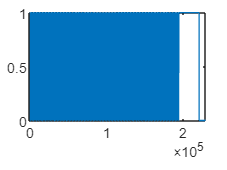

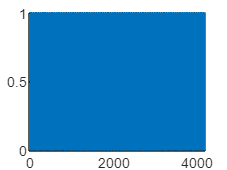

Start times:


          23          64         106         147         189         231         273         315         357         398         440         482         524         566         607         649         691         733         775         817         858         900         942         984        1026        1068        1109        1151        1193        1235        1277        1318        1360        1402        1444        1486        1528        1569        1611        1653        1695        1737        1778        1820        1862        1904        1946        1988        2029        2071        2113        2155        2197        2238        2280        2322        2364        2406        2448        2489        2531        2573        2615        2657        2699        2740        2782        2824        2866        2908        2949        2991        3033        3075        3117        3159        3200        3242        3284        3326        3368        3409        3451    

End times:


          23          64         106         147         189         231         273         315         357         398         440         482         524         566         607         649         691         733         775         817         858         900         942         984        1026        1068        1109        1151        1193        1235        1277        1318        1360        1402        1444        1486        1528        1569        1611        1653        1695        1737        1778        1820        1862        1904        1946        1988        2029        2071        2113        2155        2197        2238        2280        2322        2364        2406        2448        2489        2531        2573        2615        2657        2699        2740        2782        2824        2866        2908        2949        2991        3033        3075        3117        3159        3200        3242        3284        3326        3368        3409        3451    

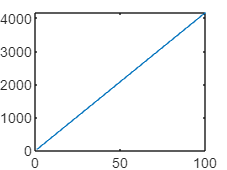

    41    42    41    42    42    42    42    42    41    42    42    42    42    41    42    42    42    42    42    41    42    42    42    42    42    41    42    42    42    42    41    42    42    42    42    42    41    42    42    42    42    41    42    42    42    42    42    41    42    42    42    42    41    42    42    42    42    42    41    42    42    42    42    42    41    42    42    42    42    41    42    42    42    42    42    41    42    42    42    42    41    42    42    42    42    42    41    42    42    42    42    41    42    42    42    42    42    41    42



save([folder_path '/Stimulus_Frame.mat'],"start_times");